% ACh sensor dose dependent, 2022.11.22
 
datapath = "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221122_AchsensorHEK001";
StateYao_file = 'analysis_offset0_ROIadjusted_20221128_v3_ROIrevision_TopPixels.mat';

cd(datapath);
load(StateYao_file);

all_epochs = [2 3 4 5 6 7 8 9 10 11 12 13]; % all the epochs
drug_epochs = [2 3 4 5 6 7 8 9 10 11 12 13];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

reference_image = '20221122_AchsensorHEK001010.tif';
num_img = 820;
acq_start = 3;

datapath = "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221122_AchsensorHEK002";
StateYao_file = 'analysis_offset0_ROIadjusted_v2_TopPixels.mat';

cd(datapath);
load(StateYao_file);

all_epochs = [2 3 4 5 6 7 8 9 10 11 12 13]; % all the epochs
drug_epochs = [2 3 4 5 6 7 8 9 10 11 12 13];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

reference_image = '20221122_AchsensorHEK002010.tif';
num_img = 846;
acq_start = 2;

[intensity_top, background_mask] = CalcIntensity_topPMT(reference_image, num_img, acq_start)

intensity_top = 1×1 cell array
    {845×5 double}


background_mask = 128×128 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();

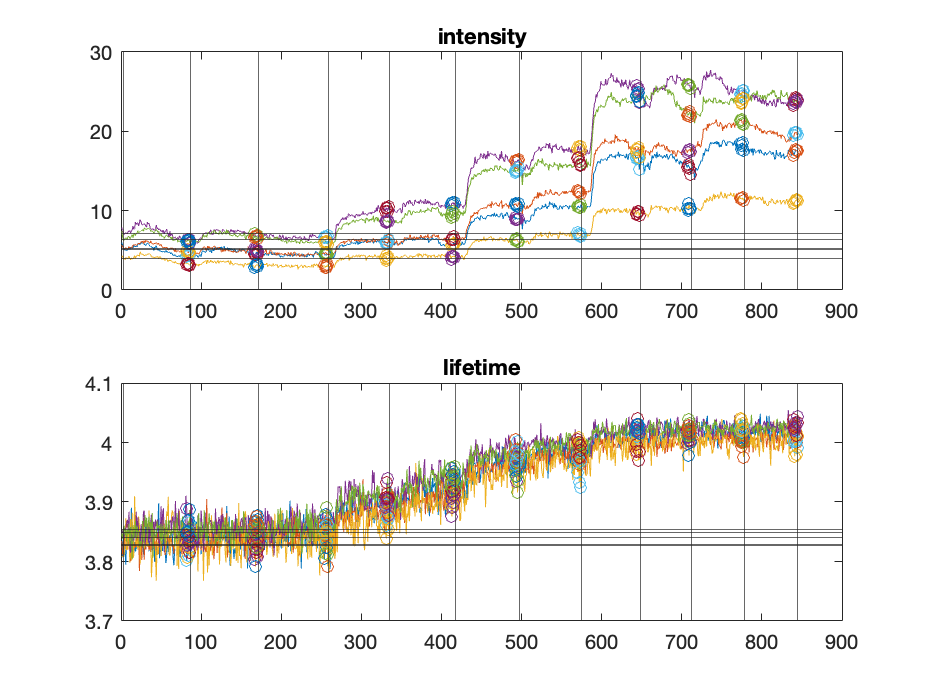

epoch_response_intensity_top_norm_all = 1×1 cell array
    {11×5 double}


epoch_response_lft_norm_all = 1×1 cell array
    {11×5 double}


epoch_response_intensity_all = 1×1 cell array
    {11×5 double}


epoch_response_lft_all = 1×1 cell array
    {11×5 double}


[epoch_response_intensity_top_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_top, lft_all)

[intensity_response_top_EC50,lft_response_EC50] = EC50_calc(drug_epochs, epoch_response_intensity_top_norm_all{1}, epoch_response_lft_all{1})

intensity_response_top_EC50 =          0         0         0         0         0
    0.0611    0.0324    0.0435    0.0698    0.0382
    0.0518    0.0045    0.0387    0.0619    0.0030
    0.1580    0.0927    0.1510    0.2345    0.1468
    0.1413    0.1158    0.1682    0.2686    0.1917
    0.3669    0.3733    0.4061    0.5338    0.4930
    0.4745    0.4686    0.4911    0.6123    0.5531
    0.8809    0.7782    0.7915    0.9703    1.0000
    0.8094    0.7813    0.8709    1.0000    0.8737
    1.0000    1.0000    1.0000    0.9545    0.9673


lft_response_EC50 =          0         0         0         0         0
   -0.0113   -0.0095    0.0916    0.0198    0.0107
    0.1018    0.0917    0.0409    0.0251   -0.0784
    0.3759    0.2867    0.1996    0.3637    0.2480
    0.4257    0.5205    0.3637    0.5430    0.4852
    0.7264    0.6996    0.6705    0.7550    0.7060
    0.8172    0.7952    0.6773    0.8524    0.7775
    0.9830    0.9555    0.9499    0.9714    0.9617
    0.9872    1.0000    1.0000    0.9826    0.9408
    0.9453    0.9842    0.9473    0.9847    1.0000


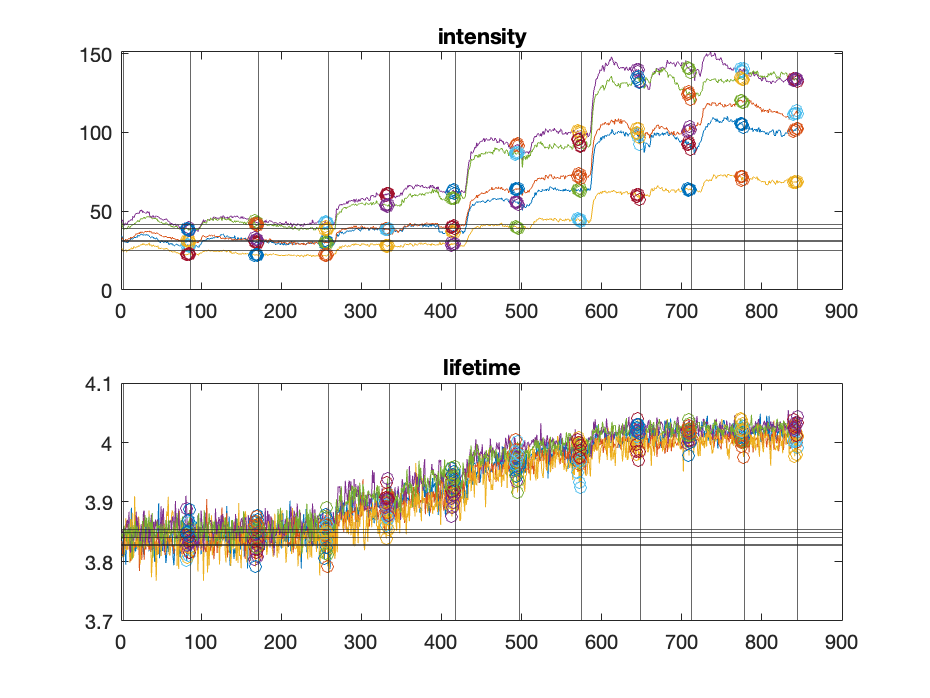

epoch_response_intensity_norm_all = 1×1 cell array
    {11×5 double}


epoch_response_lft_norm_all = 1×1 cell array
    {11×5 double}


epoch_response_intensity_all = 1×1 cell array
    {11×5 double}


epoch_response_lft_all = 1×1 cell array
    {11×5 double}


[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

[intensity_response_EC50,lft_response_EC50] = EC50_calc(drug_epochs, epoch_response_intensity_norm_all{1}, epoch_response_lft_all{1})

intensity_response_EC50 =          0         0         0         0         0
    0.0526    0.0184    0.0300    0.0686    0.0363
    0.0564   -0.0060    0.0258    0.0674    0.0059
    0.1591    0.0890    0.1456    0.2395    0.1618
    0.1394    0.1043    0.1667    0.2532    0.2085
    0.3727    0.3741    0.3774    0.5375    0.5072
    0.4742    0.4675    0.4754    0.6133    0.5780
    0.9029    0.7791    0.7694    0.9792    1.0000
    0.8382    0.7963    0.8568    1.0000    0.8947
    1.0000    1.0000    1.0000    0.9948    0.9990


lft_response_EC50 =          0         0         0         0         0
   -0.0113   -0.0095    0.0916    0.0198    0.0107
    0.1018    0.0917    0.0409    0.0251   -0.0784
    0.3759    0.2867    0.1996    0.3637    0.2480
    0.4257    0.5205    0.3637    0.5430    0.4852
    0.7264    0.6996    0.6705    0.7550    0.7060
    0.8172    0.7952    0.6773    0.8524    0.7775
    0.9830    0.9555    0.9499    0.9714    0.9617
    0.9872    1.0000    1.0000    0.9826    0.9408
    0.9453    0.9842    0.9473    0.9847    1.0000


datapath = "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/";
StateYao_file = 'analysis_offset0/20220914AChsensorHEK001_Analysis2022-09-23.mat';

all_epochs = [2 3 4 5 6]; % all the epochs
drug_epochs = [2 3 4 5 6];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

datapath = "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK002_tio/";
StateYao_file = 'analysis_offset0_ROI_adjustment/20220914AChsensorHEK002_Analysis2022-11-07.mat';

all_epochs = [2 3 4 5 6]; % all the epochs
drug_epochs = [2 3 4 5 6];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

datapath = "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK003_tio/";
StateYao_file = 'analysis_offset0/20220914AChsensorHEK003_Analysis2022-09-14.mat';

all_epochs = [2 3 4 5 6]; % all the epochs
drug_epochs = [2 3 4 5 6];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

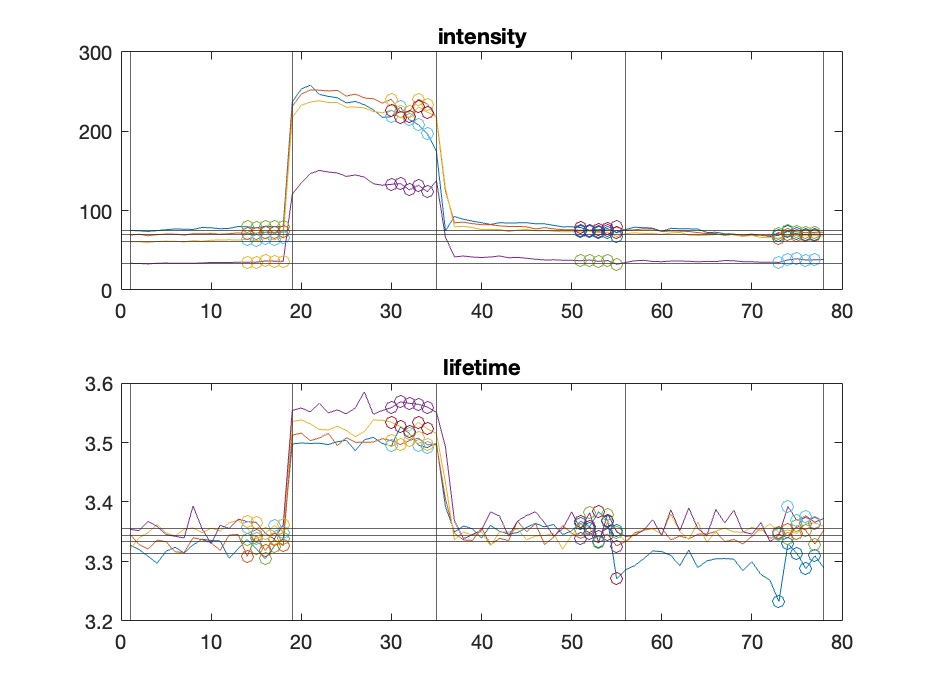

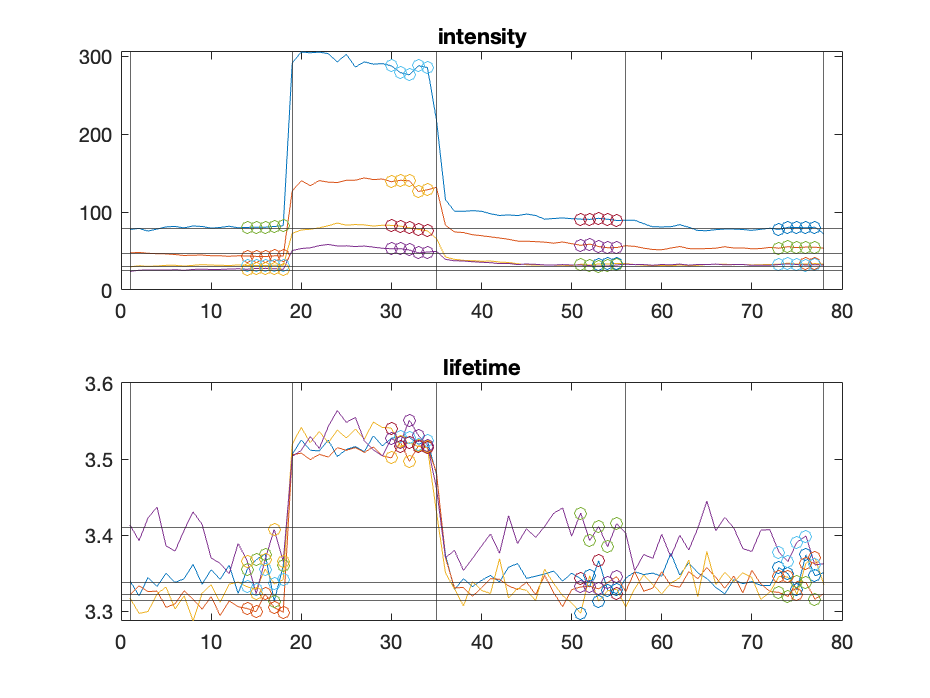

epoch_response_intensity_norm_all = 1×2 cell array
    {4×4 double}    {4×4 double}


epoch_response_lft_norm_all = 1×2 cell array
    {4×4 double}    {4×4 double}


epoch_response_intensity_all = 1×2 cell array
    {4×4 double}    {4×4 double}


epoch_response_lft_all = 1×2 cell array
    {4×4 double}    {4×4 double}


cd(datapath);
load(StateYao_file);

Yao_GUI_ReviseROIsBasedOnCoordinates()
CalculateROIBasedOnTopPixels(5, 0.66)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)